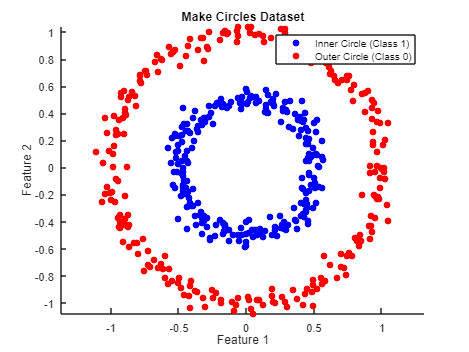

% Parameters for the dataset
num_points = 500; % Total number of points
noise_level = 0.05; % Noise level for the points

% Generate the inner and outer circles
t = linspace(0, 2*pi, num_points/2)'; % Angles for the points
r_inner = 0.5; % Radius of the inner circle
r_outer = 1.0; % Radius of the outer circle

% Inner circle points
x_inner = r_inner * cos(t) + noise_level * randn(length(t), 1);
y_inner = r_inner * sin(t) + noise_level * randn(length(t), 1);
labels_inner = ones(length(t), 1); % Label for inner circle

% Outer circle points
x_outer = r_outer * cos(t) + noise_level * randn(length(t), 1);
y_outer = r_outer * sin(t) + noise_level * randn(length(t), 1);
labels_outer = zeros(length(t), 1); % Label for outer circle

% Combine the inner and outer circle points
X = [x_inner, y_inner; x_outer, y_outer]; % Features (2D)
Y = [labels_inner; labels_outer]; % Labels

% Scatter plot of the generated dataset
figure;
scatter(x_inner, y_inner, 'b', 'filled'); hold on;
scatter(x_outer, y_outer, 'r', 'filled');
title('Make Circles Dataset');
xlabel('Feature 1');
ylabel('Feature 2');
legend('Inner Circle (Class 1)', 'Outer Circle (Class 0)');
axis equal;


% Save to CSV if needed
dataset = [X, Y];
csvwrite('make_circles_dataset.csv', dataset);

disp('Dataset created and saved as make_circles_dataset.csv');

Dataset created and saved as make_circles_dataset.csv
